R
     1     0     0
     0     1     0
     0     0     1

euler
     0     0     0

R
    1.0000   -0.0637   -0.1208
    0.0637    1.0000    0.2415
    0.1208   -0.2415    1.0000

euler
    0.0636   -0.1200   -0.2370

R
    1.1653   -0.0802    1.2567
   -0.5095    1.6067   -2.1190
   -1.0343    2.2304    1.7366

euler
   -0.4121    0.6827    0.9092

R
   17.1266  -40.2788  -16.1105
  -20.4266   62.4670   48.8161
   32.1539  -40.7444   76.6973

euler
   -0.8730   -0.8786   -0.4883

R
   1.0e+04 *

    0.0941   -0.5655    1.5003
   -0.1589    1.7725   -2.3209
    0.0438    2.9037    1.5354

euler
   -1.0360   -0.2330    1.0844

R
   1.0e+08 *

    0.9813   -0.6019   -0.2882
   -1.5075    0.9313    0.8141
    1.0450   -0.6150    1.1339

euler
   -0.9938   -0.5263   -0.4969

R
   1.0e+13 *

   -1.0098   -2.1343    1.0188
    2.8567    6.0358   -1.6149
    3.9908    8.4263    0.8921

euler
    1.9106   -0.9214    1.4653

R
   1.0e+21 *

    4.1116   -2.0495   -0.2184
   -6.5169    3.2485 

close all;
clc; clear;
clearvars;
addpath('lib')

%% DEFINE
R2D = 180/pi;
D2R = pi/180;

%% INIT. PARAMS.

drone_params = containers.Map({'mass','gyro','inertialMatrix'},...
    {0.467, [0.2, 0.1, -0.1]',diag([8.28, 8.28, 15.7]*10^-3)});

% drone_params = containers.Map({'mass','gyro','inertialMatrix'},...
%     {0.467, [0, 0, 0]',diag([8.28, 8.28, 15.7]*10^-3)});

drone_initStates = containers.Map({'position','velocity','attitude','angularV' }, ...
    {[0, 0, 0.1]',[0,0,0]',eye(3),zeros(3,1)}); 



drone_initInputs = [0, 0, 0, 0]';                                                                  % R, P, Y CMD

drone_body = [ 0.265,      0,     0, 1; ...
                    0, -0.265,     0, 1; ...
               -0.265,      0,     0, 1; ...
                    0,  0.265,     0, 1; ...
                    0,      0,     0, 1; ...
                    0,      0, -0.15, 1]';
			  

%% BIRTH OF A DRONE

simulationTime = 5;  
drone = Drone(drone_params, drone_initStates, drone_initInputs,simulationTime);


%% Simulation time


ts = 0.1;
t = 0:ts:simulationTime;



%% desired trajectory
% ****** Example 01 *******

n = length(t);
trajectoryD = zeros(3, n);

% Define the function xd(t)
xd = 2.5 * cos(2 * pi / 60 * t);
yd = 3 * sin(2 * pi / 60 * t) .* cos(2 * pi / 60 * t);
zd = 5 * ones(size(t));

% trajectoryD = [xd, yd, zd]';

for i = 1:n
    trajectoryD(1, i) = 2.5 * cos(2 * pi / 60 * t(i));
    trajectoryD(2, i) = 3 * sin(2 * pi / 60 * t(i)) .* cos(2 * pi / 60 * t(i));
    trajectoryD(3, i) = 5 * ones(size(t(i)));
end

% Mostrar la matriz
%disp(trajectoryD);

% Definir el parámetro t como un vector que va de 0 a 60 en pasos de 0.1
tf = 0:0.1:60;

% Calcula las coordenadas x, y, z de la función en cada valor de t
x = 2.5 * cos(2*pi/60 * tf);
y = 3 * sin(2*pi/60 * tf) .* cos(2*pi/60 * tf);
z = 5 * ones(size(tf));

% ****** Example 02 *******
% xrd = 2.5*cos(0.2*t);
% yrd = 2.5*sin(0.4*t);
% zrd = 7*ones(1,length(t));

%% desired position

% xd = randi([-5 5]);
% yd = randi([-5 5]);
% zd = randi([0 9]);

% xd = 5;
% yd = 5;
% zd = 5;
% 
% trajectoryD = [xd, yd, zd];



%% Starting simulation
% Define initial figure properties
figure('Position', [0, 200, 800, 800]);
fig_trajectory = figure('Position', [0, 200, 800, 800]);
view(3);
axis square;
grid on;
grid minor;
axis([-5, 5, -5, 5, 0, 9]);
xlabel('X[m]');
ylabel('Y[m]');
zlabel('Height[m]');
hold on;



% Plot desired position
% Plot the function xd(t)

plot3(x, y, z, 'r:', 'LineWidth', 0.1);

%plot3(xd, yd, zd, 'r:', 'LineWidth', 0.1);
%legend('Trajectory of the drone', 'Function xd(t)');


% Initialize plot variables
drone1_state = drone.GetState();
wHb = [RPY2Rot([drone.phi, drone.theta, drone.psi])', drone1_state.s(1:3); 0, 0, 0, 1];
drone1_world = wHb * drone_body;
drone1_atti = drone1_world(1:3, :);

% Initialize trajectory plot with starting point
trajectory_plot = plot3(drone1_state.s(1), drone1_state.s(2), drone1_state.s(3), 'b-', 'LineWidth', 0.5);
%legend('Trajectory of the drone');

fig1_ARM13 = line(drone1_atti(1,[1, 3]), drone1_atti(2,[1, 3]), drone1_atti(3,[1, 3]), 'Color', 'r', 'Marker', 'o', 'MarkerSize', 5);
fig1_ARM24 = line(drone1_atti(1,[2, 4]), drone1_atti(2,[2, 4]), drone1_atti(3,[2, 4]), 'Color', 'b', 'Marker', 'o', 'MarkerSize', 5);
fig1_payload = line(drone1_atti(1,[5, 6]), drone1_atti(2,[5, 6]), drone1_atti(3,[5, 6]), 'Color', 'k', 'LineWidth', 3);
fig1_shadow = line(0, 0, 0, 'Color', 'k', 'Marker', 'x', 'LineWidth', 3);

% Add a line indicating the front of the drone
front_vector = drone1_atti(:,1) + 0.5 * (drone1_atti(:,3) - drone1_atti(:,1));
fig1_front = line([drone1_atti(1,1), front_vector(1)], [drone1_atti(2,1), front_vector(2)], [drone1_atti(3,1), front_vector(3)], 'Color', 'g', 'LineWidth', 2, 'DisplayName', 'Front');




%scatter3(xrd, yrd, zrd, 'ro', 'LineWidth', 3);

% Create figure for state viewer
fig_handle = figure('Name', 'Drone state viewer', 'NumberTitle', 'off', 'Position', [960, 0, 960, 1080]);
tg = uitabgroup;

% Define tab and subplot properties for Position, Velocity, and Attitude tabs
tabs = {'Position', 'Velocity', 'Attitude'};
for idx = 1:3
    current_tab = uitab(tg, 'Title', tabs{idx});
    axes('Parent', current_tab);
    for i = 1:3
        subplot(3, 1, i);
        grid on;
        grid minor;
        hold on;
    end
end

% Initialize tracking variables
dt = 0.1; % Time step
timeF = 0:dt:simulationTime;
xt = zeros(size(timeF));
yt = zeros(size(timeF));
zt = zeros(size(timeF));
xvt = zeros(size(timeF));
yvt = zeros(size(timeF));
zvt = zeros(size(timeF));
rollt = zeros(size(timeF));
pitcht = zeros(size(timeF));
yawt = zeros(size(timeF));

% Inicialización de matrices para la posición, velocidad y aceleración deseadas
pos_des_all = zeros(3, length(timeF));
vel_des_all = zeros(3, length(timeF));
acc_des_all = zeros(3, length(timeF));

for i = 1:length(timeF)
    % Calcula la posición deseada
    pos_des_all(1, i) = 2.5 * cos(2 * pi / 60 * timeF(i));
    pos_des_all(2, i) = 3 * sin(2 * pi / 60 * timeF(i)) .* cos(2 * pi / 60 * timeF(i));
    pos_des_all(3, i) = 5; % Esto es constante, así que puedes incluso sacarlo del bucle
end

% Calcula la velocidad y aceleración deseada para toda la trayectoria (excepto en los extremos)
for i = 2:length(timeF) - 1
    vel_des_all(:, i) = (pos_des_all(:, i+1) - pos_des_all(:, i-1)) / (2 * timeF(i));
    acc_des_all(:, i) = (pos_des_all(:, i+1) - 2*pos_des_all(:, i) + pos_des_all(:, i-1)) / (timeF(i)^2);
end


for i = 1:length(timeF)
    % Update drone state
    % drone.PositionCtrl(trajectoryD(:,i));
    drone.PositionCtrl(pos_des_all(:,i), vel_des_all(:,i), acc_des_all(:,i));
    drone.UpdateState();
    drone1_state = drone.GetState();

    wHb = [RPY2Rot([drone.phi, drone.theta, drone.psi])', drone1_state.s(1:3); 0, 0, 0, 1];
    drone1_world = wHb * drone_body;
    drone1_atti = drone1_world(1:3, :);

    % Update tracking variables
    xt(i) = drone1_state.s(1);
    yt(i) = drone1_state.s(2);
    zt(i) = drone1_state.s(3);
    xvt(i) = drone1_state.s(4);
    yvt(i) = drone1_state.s(5);
    zvt(i) = drone1_state.s(6);

    aux = rotm2eul(drone1_state.R);
    rollt(i) = aux(1);
    pitcht(i) = aux(2);
    yawt(i) = aux(3);

     % Update 3D drone visualization
    set(fig1_ARM13, 'XData', drone1_atti(1,[1, 3]), 'YData', drone1_atti(2,[1, 3]), 'ZData', drone1_atti(3,[1, 3]));
    set(fig1_ARM24, 'XData', drone1_atti(1,[2, 4]), 'YData', drone1_atti(2,[2, 4]), 'ZData', drone1_atti(3,[2, 4]));
    set(fig1_payload, 'XData', drone1_atti(1,[5, 6]), 'YData', drone1_atti(2,[5, 6]), 'ZData', drone1_atti(3,[5, 6]));
    set(fig1_shadow, 'XData', drone1_state.s(1), 'YData', drone1_state.s(2));

    % Update the front of the drone
    front_vector = drone1_atti(:,1) + 0.5 * (drone1_atti(:,3) - drone1_atti(:,1));
    set(fig1_front, 'XData', [drone1_atti(1,1), front_vector(1)], 'YData', [drone1_atti(2,1), front_vector(2)], 'ZData', [drone1_atti(3,1), front_vector(3)]);

    figure(fig_trajectory);

    % Update trajectory plot
    set(trajectory_plot, 'XData', xt(1:i), 'YData', yt(1:i), 'ZData', zt(1:i));

    drawnow;

    % Stop if drone crashes
    if (drone1_state.s(3) <= 0)
        msgbox('Stop');
        break;
    end
end


% Graficar los resultados finales

figure('Position', [0, 200, 800, 800]);
view(3);
axis square;
grid on;
grid minor;
axis([-5, 5, -5, 5, 0, 9]);
xlabel('X[m]');
ylabel('Y[m]');
zlabel('Height[m]');
hold on;

%scatter3(xd, yd, zd, 'ro', 'LineWidth', 3);
line(xt, yt, zt, 'Color', 'm', 'LineStyle', '-.', 'LineWidth', 1.5);

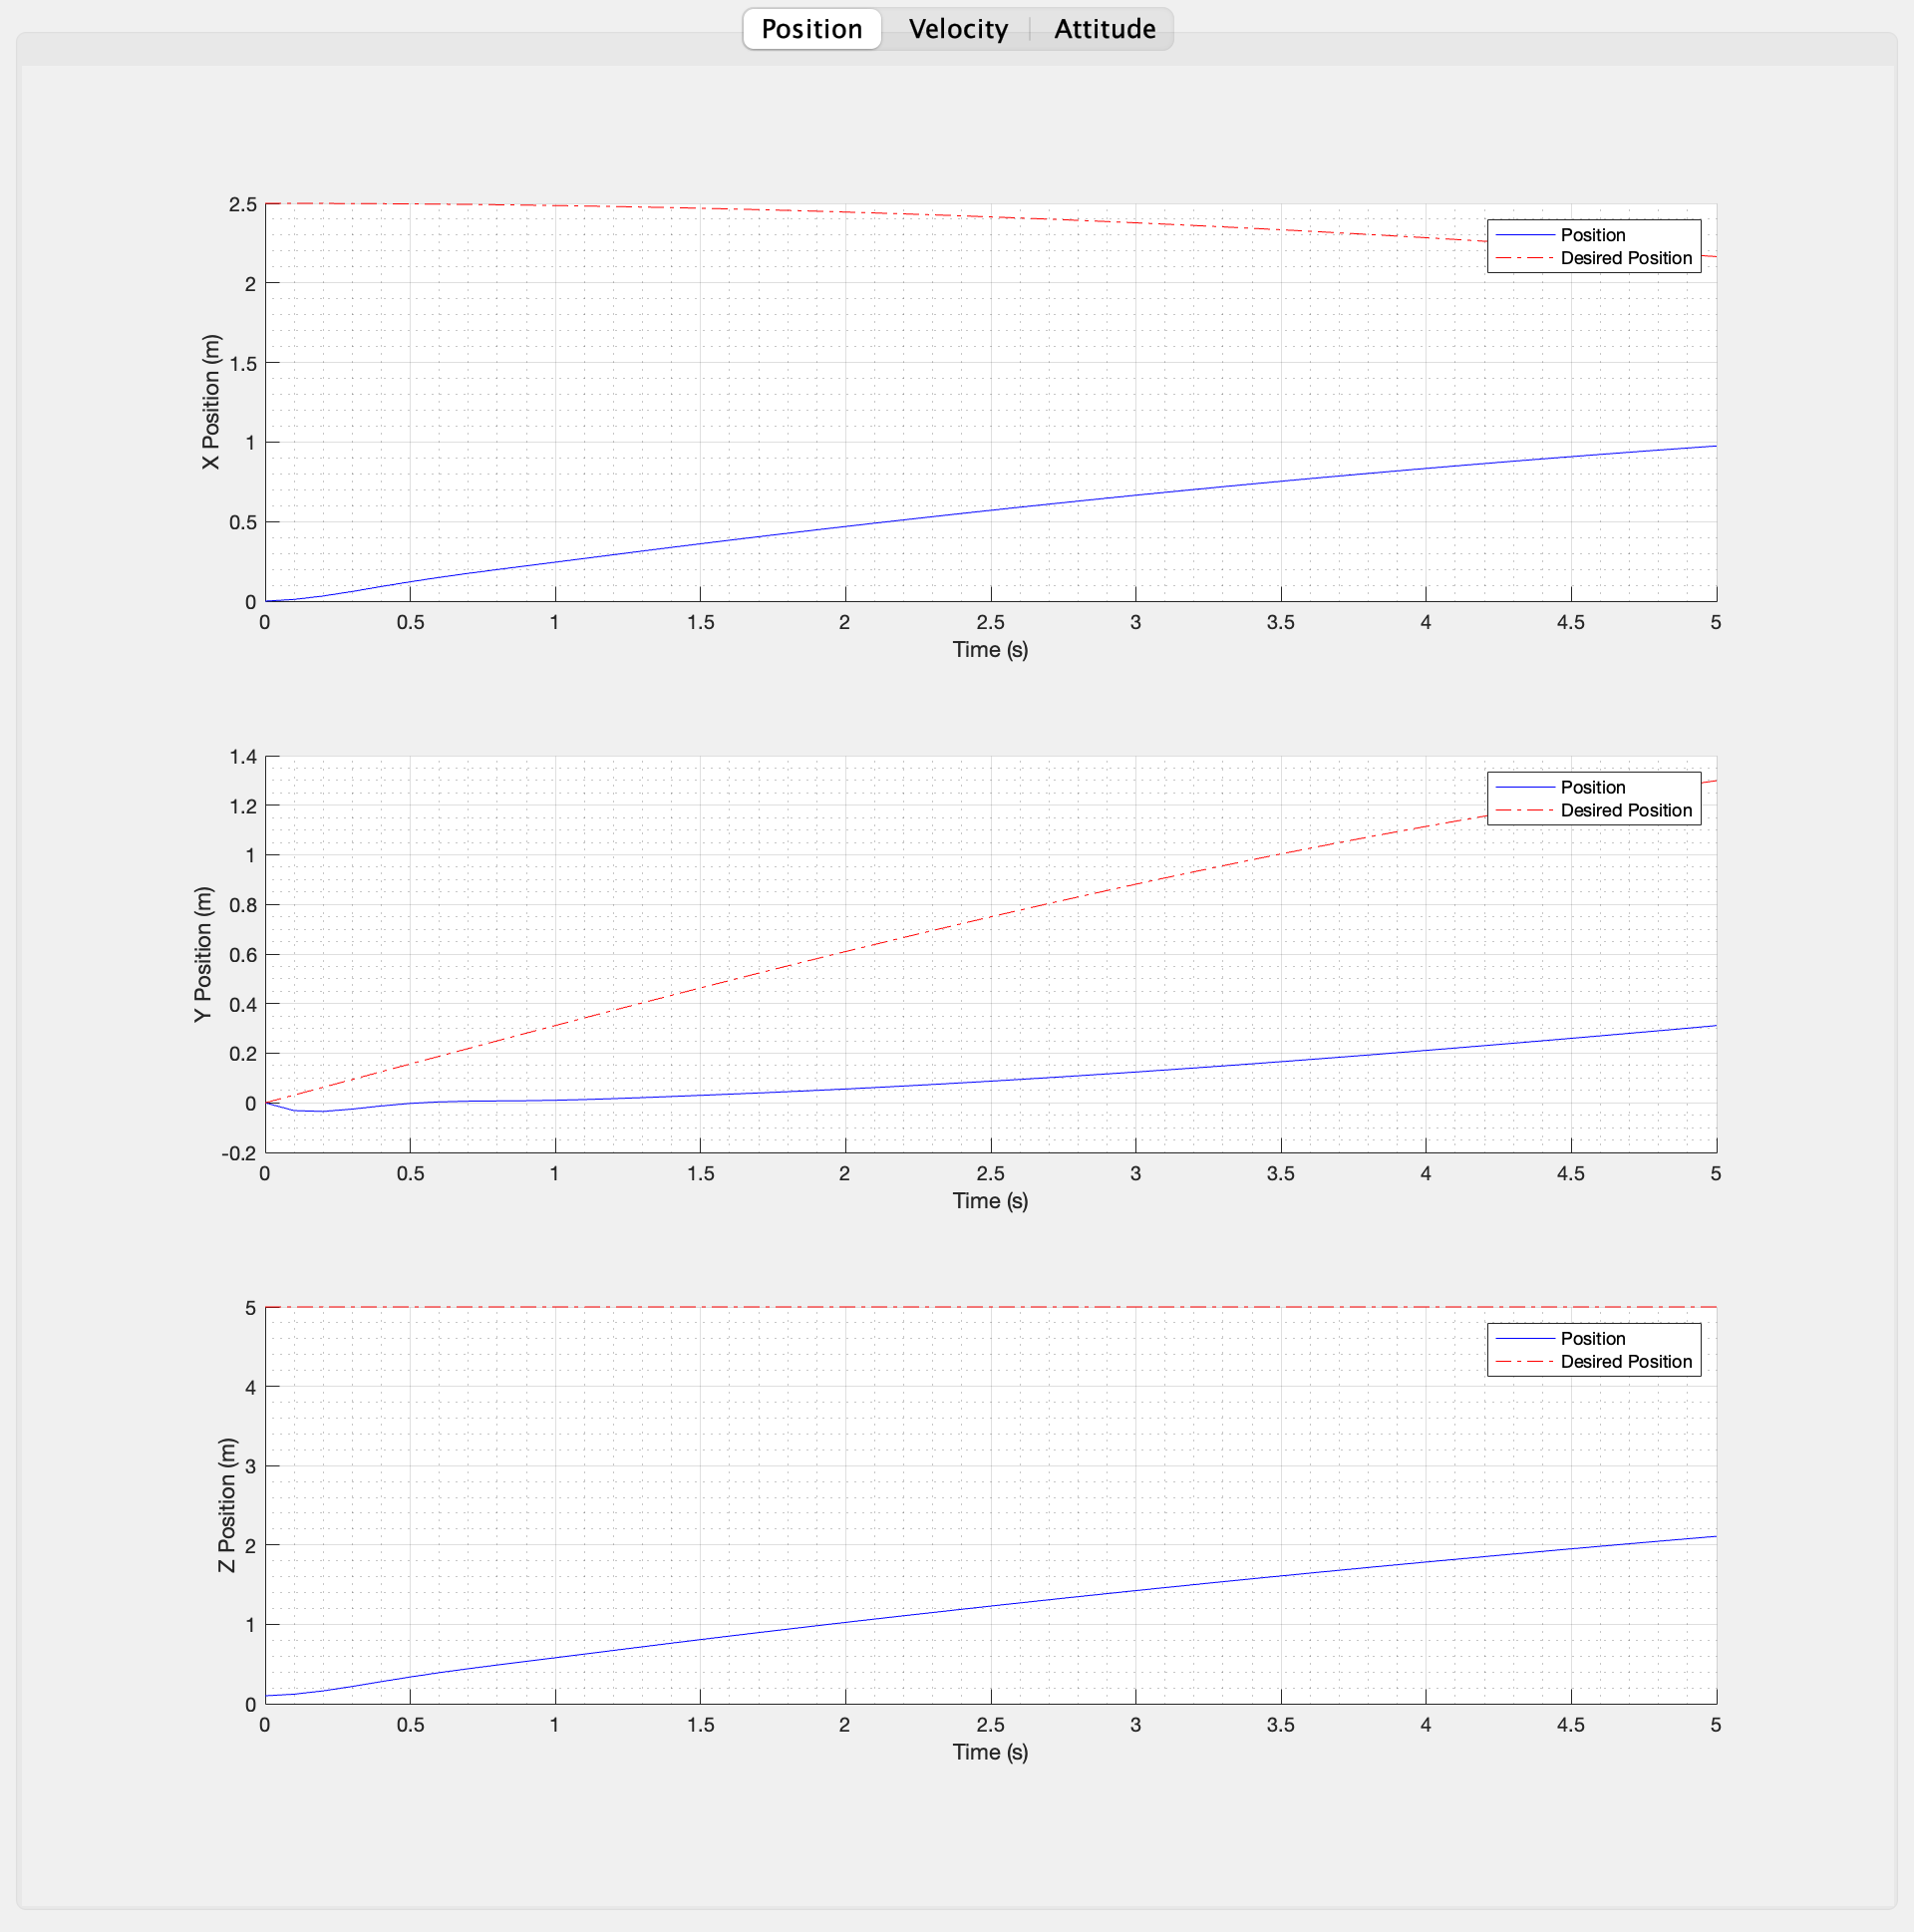




updateStateViewer(fig_handle, tg, timeF, xt, yt, zt, xvt, yvt, zvt, rollt, pitcht, yawt, xd, yd, zd);


% Define function to update the state viewer plots

function updateStateViewer(fig_handle, tg, timeF, xt, yt, zt, xvt, yvt, zvt, rollt, pitcht, yawt, xd, yd, zd)
    figure(fig_handle);

    % Update position plots
    axes('Parent', tg.Children(1));
    subplot(3, 1, 1);
    h1 = plot(timeF, xt, 'b');
    h2 = plot(timeF, xd, 'r-.');  % Use plot instead of yline
    xlabel('Time (s)');
    ylabel('X Position (m)');
    legend([h1, h2], {'Position', 'Desired Position'});

    subplot(3, 1, 2);
    h1 = plot(timeF, yt, 'b');
    h2 = plot(timeF, yd, 'r-.');  % Use plot instead of yline
    xlabel('Time (s)');
    ylabel('Y Position (m)');
    legend([h1, h2], {'Position', 'Desired Position'});

    subplot(3, 1, 3);
    h1 = plot(timeF, zt, 'b');
    h2 = plot(timeF, zd, 'r-.');  % Use plot instead of yline
    xlabel('Time (s)');
    ylabel('Z Position (m)');
    legend([h1, h2], {'Position', 'Desired Position'});

    % Update velocity plots
    axes('Parent', tg.Children(2));
    subplot(3, 1, 1);
    plot(timeF, xvt, 'b');
    xlabel('Time (s)');
    ylabel('X Velocity (m/s)');
    
    subplot(3, 1, 2);
    plot(timeF, yvt, 'b');
    xlabel('Time (s)');
    ylabel('Y Velocity (m/s)');

    subplot(3, 1, 3);
    plot(timeF, zvt, 'b');
    xlabel('Time (s)');
    ylabel('Z Velocity (m/s)');

    % Update attitude plots
    axes('Parent', tg.Children(3));
    subplot(3, 1, 1);
    plot(timeF, rollt, 'b');
    xlabel('Time (s)');
    ylabel('Roll Angle (rad)');

    subplot(3, 1, 2);
    plot(timeF, pitcht, 'b');
    xlabel('Time (s)');
    ylabel('Pitch Angle (rad)');

    subplot(3, 1, 3);
    plot(timeF, yawt, 'b');
    xlabel('Time (s)');
    ylabel('Yaw Angle (rad)');
end






